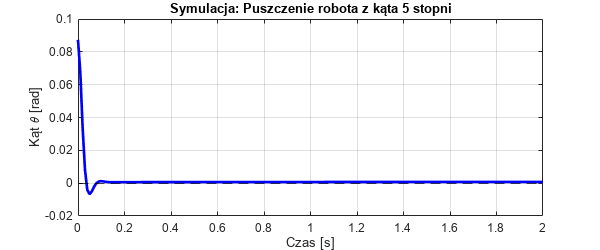

%% PARAMETRY SYMULACJI
kat_start_stopnie = 5;          % Startujemy z wychylenia 10 stopni
Tf = 0.01;                       % Stała czasowa filtra różniczkowania (konieczna!)
czas_symulacji = 2;

% Twoje nastawy (po modyfikacji)
Kp_sim = Kp; % Twoja modyfikacja
Ki_sim = Ki;      % Oryginał z Z-N (uwaga: może być za duży!)
Kd_sim = Kd;        % Oryginał z Z-N

%% 1. PRZYGOTOWANIE MODELU (State Space)
% Musimy użyć macierzy A, B, C, D, które masz z poprzednich kroków
% (Zakładam, że są w workspace. Jeśli nie, przeklej je tu z poprzednich skryptów)
Sys_plant = ss(A, B, C, D);

%% 2. PRZYGOTOWANIE REGULATORA
% Tworzymy obiekt PID z filtrem (bez filtra Tf nie połączysz tego w state-space)
Regulator = pid(Kp_sim, Ki_sim, Kd_sim, Tf);

%% 3. ZAMKNIĘCIE PĘTLI
% Łączymy regulator z obiektem:
% Uchyb -> Regulator -> Obiekt -> Wyjście
% Układ zamknięty (feedback ujemny)
Sys_closed = feedback(Sys_plant * Regulator, 1);

%% 4. DEFINICJA WARUNKU POCZĄTKOWEGO (To jest klucz!)
% Twój wektor stanu robota to: [x, theta, dx, dtheta]
% Regulator PID dokłada swoje stany (całka + filtr), zazwyczaj na początku lub końcu.

% Sprawdźmy ile mamy stanów łącznie (Robot=4 + PID=2 = 6 stanów)
num_states = size(Sys_closed.A, 1);

% Tworzymy wektor zer
x0 = zeros(num_states, 1);

% Musimy znaleźć, który stan to "Theta" w układzie zamkniętym.
% Zazwyczaj przy mnożeniu (Sys_plant * Regulator), stany obiektu są PIERWSZE.
% W Twoim modelu A: x(1)=x, x(2)=theta.
% Więc ustawiamy drugi stan na 10 stopni.
x0(2) = deg2rad(kat_start_stopnie); 

% (Gdyby wykres startował od 0, to znaczy, że MATLAB zamienił kolejność stanów.
% Wtedy trzeba by spróbować np. x0(end-2) = ... ale zazwyczaj x0(2) jest ok).

%% 5. SYMULACJA I WYKRES
t = 0:0.01:czas_symulacji;
[y, t] = initial(Sys_closed, x0, t);

figure('Position', [100, 100, 600, 250]);
plot(t, y, 'b', 'LineWidth', 2);
grid on;
title(['Symulacja: Puszczenie robota z kąta ' num2str(kat_start_stopnie) ' stopni']);
xlabel('Czas [s]');
ylabel('Kąt \theta [rad]');
yline(0, 'k--');

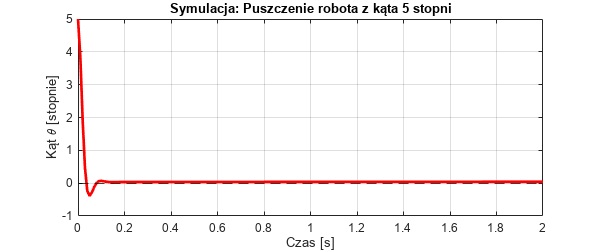


% Dodatkowy wykres w stopniach (bardziej czytelny dla człowieka)
figure('Position', [100, 100, 600, 250]);
plot(t, rad2deg(y), 'r', 'LineWidth', 2);
grid on;
title(['Symulacja: Puszczenie robota z kąta ' num2str(kat_start_stopnie) ' stopni']);
xlabel('Czas [s]');
ylabel('Kąt \theta [stopnie]');
yline(0, 'k--');
print('Puszczenie robota zigler.png', '-dpng', '-r400');